clear all
close all
clc

% Declaration of symbolic variables
x=sym('x',[3 1],'real');
u=sym('u',[1 1],'real'); 


## Plant definition



a=10.4;
b=16.5;
R=0;
q=-1.16*x(1)+0.041*x(1)^3;

% figure
% ezplot(q,[-3 3])
% xlabel('$x_1$','interpreter','latex','fontsize',20)
% ylabel('$\rho(x_1)$','interpreter','latex','fontsize',20)
% grid
% return

f=[a*(x(2)-x(1)-q)
    x(1)-x(2)+x(3)
    -b*x(2)-R*x(3)]

g=[0;1;0];

h=x(1);
C=[1 0 0];

xd=f+g*u;

matlabFunction(xd,'File','fg_chua','Vars',{[u;x]});
%return

%% Feedback linearization 

[u,mu,ga]=io_fl(f,g,h,'chua')

$$u = \frac{5\,v}{52}-x_{1}+x_{2}-x_{3}+\frac{5\,\left(\frac{1599\,{x_{1}}^{2}}{1250}-\frac{208}{125}\right)\,\left(-\frac{533\,{x_{1}}^{3}}{1250}+\frac{208\,x_{1}}{125}+\frac{52\,x_{2}}{5}\right)}{52}$$

$$mu = \left(\begin{array}{c} x_{1}\\ -\frac{533\,{x_{1}}^{3}}{1250}+\frac{208\,x_{1}}{125}+\frac{52\,x_{2}}{5} \end{array}\right)$$

ga = 2

%return

%% Linear controller 

A=[0 1
    0 0];

B=[0;1];

K=place(A,B,[-1 -2]);
%return


## Simulation



ref='sin(2*t)';
%ref='1';
yr=ref_gen(ga,ref,'chua');

tfin=60;
x0=randn(3,1)*0;

%open('lab_2a')
res = sim('lab_2a')

res =   Simulink.SimulationOutput:

              resulting: [1x1 timeseries] 
               stateres: [1x1 timeseries] 
                   tout: [179x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


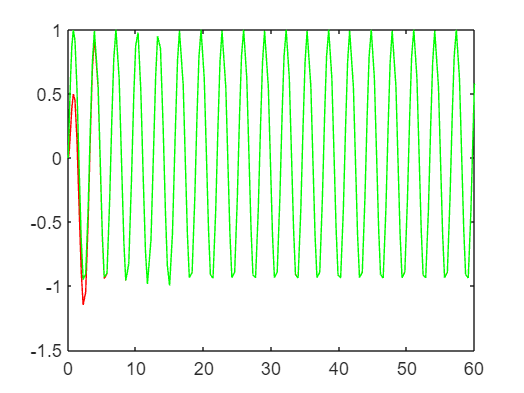

time = res.resulting.Time;
data1 = res.resulting.Data(:,1);
data2 = res.resulting.Data(:,2);

time_s = res.stateres.Time;
state1 = res.stateres.Data(:,1);
state2 = res.stateres.Data(:,2);
state3 = res.stateres.Data(:,3);

figure(1)
plot(time, data2,  "r");
hold on 
plot( time, data1, "g")
hold off

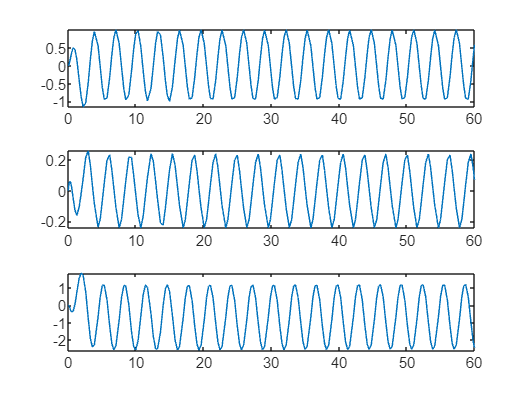


figure(2)
tiledlayout(3,1);
nexttile;
plot(time, state1)
nexttile;
plot(time, state2)
nexttile;
plot(time, state3)
hold off

## R == 0


R=0;
res = sim('lab_2a')

res =   Simulink.SimulationOutput:

              resulting: [1x1 timeseries] 
               stateres: [1x1 timeseries] 
                   tout: [179x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


time = res.resulting.Time;
data1 = res.resulting.Data(:,1);
data2 = res.resulting.Data(:,2);

time_s = res.stateres.Time;
state1 = res.stateres.Data(:,1);
state2 = res.stateres.Data(:,2);
state3 = res.stateres.Data(:,3);

figure(3)
plot(time, data2,  "r");
hold on 
plot( time, data1, "g")
hold off


figure(4)
tiledlayout(3,1);
nexttile;
plot(time, state1)
nexttile;
plot(time, state2)
nexttile;
plot(time, state3)
hold off


%% Excercise 3
eig_des = [-5, -9, -7.5]

eig_des =    -5.0000   -9.0000   -7.5000



A = jacobian(f,x)

$$A = \left(\begin{array}{ccc} \frac{208}{125}-\frac{1599\,{x_{1}}^{2}}{1250} & \frac{52}{5} & 0\\ 1 & -1 & 1\\ 0 & -\frac{33}{2} & 0 \end{array}\right)$$

A = subs(A,x,[0; 0; 0])

$$A = \left(\begin{array}{ccc} \frac{208}{125} & \frac{52}{5} & 0\\ 1 & -1 & 1\\ 0 & -\frac{33}{2} & 0 \end{array}\right)$$

B = [0;1;0]

B =      0
     1
     0


K = place(A,B,eig_des)

$$K = \left(\begin{array}{ccc} \frac{3188390256947973}{281474976710656} & -\frac{1657610050637751}{1125899906842624} & -\frac{4356532735881847}{281474976710656} \end{array}\right)$$